F = [0, 0];
R = 0.20;
g = 9.81;
m = 6.8;
my = 0.05;

Friction = my*m*g;

I = 2/5 * m * R^2;

N = 50000;
v = zeros(N+1, 2);
w = zeros(N+1, 2);
pos = zeros(N+1, 2);

rolling = [false false];

v(1,1) = 4.5;
v(1,2) = 2;

h = 0.0001;

time = 0:h:N*h;
for t = 1:N
    for axel = 1:2
        F_sum = 0;
        if(t <= 10)
            F_sum = F_sum + F(axel);
        end
        
        if v(t, axel) > 0.002
            F_sum = F_sum - Friction;
        elseif v(t, axel) < -0.002
            F_sum = F_sum + Friction;
        else
            v(t, axel) = 0;
        end
    
        a = 1/m * F_sum;
        if(abs(a) <= 0.0002)
            a = 0;
        end
        Tnet = sum(-0.02);
        if(rolling(axel) == false)
            Tnet = Tnet + R*Friction;
        end
        alpha = Tnet/I;
    
        w(t+1, axel) = impEuler(w(t, axel),alpha,h);
        v(t+1, axel) = impEuler(v(t, axel),a,h);

        %TODO: FIX IF STATMENT
        if abs(v(t+1, axel) - R*w(t+1, axel)) < 0.0002 || rolling(axel)
            if rolling(axel) == false
                time(N)
            end
            rolling(axel) = true;
            pos(t+1, axel) = impEuler(pos(t, axel),w(t+1, axel)*R, h);
        else
            pos(t+1, axel) = impEuler(pos(t, axel),v(t+1, axel), h);
        end
    end
end

ans = 4.9999

ans = 4.9999

## Animation

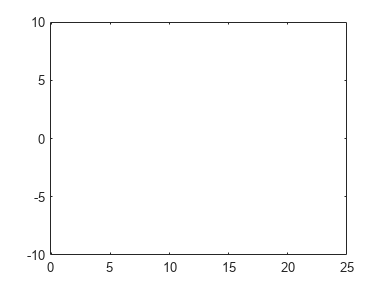


for k = 1:length(pos(:,1)) 
     plot(pos(k,1),pos(k,2),'r*')
     axis([-0.1 25 -10 10])
     hold on
     pause(0.01)
     if k ~= length(pos(:,1))
        clf
     end
end
hold off

## Plot Data

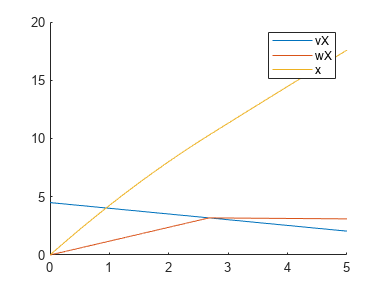

figure;
hold on
plot(time, v(:,1))
plot(time,w(:,1)*R)
plot(time,pos(:,1))
legend("vX","wX","x")
hold off

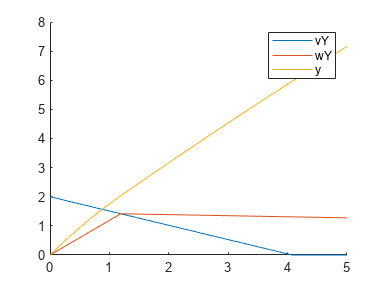


figure;
hold on
plot(time,v(:,2))
plot(time,w(:,2)*R)
plot(time,pos(:,2))
legend("vY","wY","y")